**BE MATLAB VFEA**

**FISA 2A**

*=> GROUP : *

- *BABIN-RIBY Hugo*

- *BUFFARD-MICELI Eliot*

clear all;
%VARIABLES INIT
E = 7*10^10;    % Pa / YOUNG MODULE 
rho = 2750;     % kg/m3 / Volumic mass
L = 340;        % mm / total lenght of considered rod
b = 22;         % mm / side lenght of section
t = 2;          % mm / side lenght of section
S = b * t;      % mm^2 / Section
I =  (b*t^3)/12;% mm^4 / quadratic moment

%Number of elements, to modify depending on the case
nel = 30;       % nel, value to modify in order to see the impact of the number of elements
nn = nel + 1;   % nombre noeuds = ndegliberté
l0 = L / nel;   % lenght of an element
kmax = L/l0;    % kmax
c0 = sqrt(E/rho); % célérité dans la matière

***nel*** is the value controlling the n umber of element.

We can change it and re-run the code to see the impact on the frequencies values

% Mass and stiffness matrix of one element.
mc = [2 1 ; 1 2] * (rho*S*l0/6);
md = [3 0 ; 0 3] * (rho*S*l0/6);
k = [1 -1 ; -1 1] * (E*S/l0);

%ASSEMBLE MATRIXES

% make M mass matrix
M = zeros(nn,nn);
%assamble M
for el = 1:nn-1 % boucle sur les éléments
    M(el:el+1,el:el+1) = mc + M(el:el+1,el:el+1);
end
disp("M mass matrix :")

M mass matrix :


disp(M / (rho*S*l0/6)); %display only coeficients in order to check if is good

     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     4     1     0     0     0     



%make K stiffness matrix 
K = zeros(nn,nn);
%assamble K
for el = 1:nn-1
    K(el:el+1,el:el+1) = k + K(el:el+1,el:el+1);
end
disp("K stiffness matrix :")

K stiffness matrix :


disp(K / (E*S/l0)); %display only coeficients in order to check if is good

     1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0     


% We also make an Md matrix, using the diagonal mass matrix for furthuer
% comparaisons
Md = zeros(nn,nn);
%assamble M
for el = 1:nn-1 % boucle sur les éléments
    Md(el:el+1,el:el+1) = md + Md(el:el+1,el:el+1);
end

disp("Md diagonal mass matrix (for comparaison at the end) :")

Md diagonal mass matrix (for comparaison at the end) :


disp(Md / (rho*S*l0/6)); %display only coeficients in order to check if is good

     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     6     0     0     0     0     

**Conclusion :**

- We declared mass and stiffness matrix for each element

- We loop for each elements and added element matrix to global matrix at the right coordonates

- We now have K and M that we displayed and devided by the material-dependent factor in order to check the coefficient

- Everyhting is good, we can moove on

%CASE : Clamped-free rod

% solve for w, natural frequencies of the barsm.
% USING EIG from MATLAB:

K1 = K(2:end, 2:end);
M1 = M(2:end, 2:end);
[~,wnDiag] = eig(K1,M1);
wnEig = sqrt(diag(wnDiag));
disp("Case 1 : Natural frequencies using eig()");

Case 1 : Natural frequencies using eig()


disp(wnEig');

   1.0e+03 *

    0.0233    0.0700    0.1169    0.1641    0.2117    0.2600    0.3089    0.3587    0.4094    0.4613    0.5144    0.5688    0.6246    0.6820    0.7410    0.8015    0.8636    0.9272    0.9919    1.0575    1.1234    1.1889    1.2530    1.3145    1.3721    1.4239    1.4683    1.5035    1.5280    1.5405





% USING THERORY :

%x= 0 => U=0
%x = L => U' = 0 (deformation =0)
%
% on applique les CLs, cela donne =>
% Csin(0) + Dcos(0) = 0 => d = 0
% U'(L) = 0 = (w/c0)C*cos(wL/c0)
% ommiting trivial solution w = 0  we get the equation :
% w = (c0/L)(2k -1)(pi/2)

% We go through k = 1  to 10 to computute 10 first mode
wnTh = zeros(nel,1);
for k = 1:nel % boucle sur les modes de fréquences
    wnTh(k) = (c0/L)*(2*k-1)*(pi/2);
end

disp("Case 1 : Natural frequencies using theory");

Case 1 : Natural frequencies using theory


disp(wnTh');

   1.0e+03 *

    0.0233    0.0699    0.1165    0.1632    0.2098    0.2564    0.3030    0.3496    0.3963    0.4429    0.4895    0.5361    0.5827    0.6293    0.6760    0.7226    0.7692    0.8158    0.8624    0.9091    0.9557    1.0023    1.0489    1.0955    1.1421    1.1888    1.2354    1.2820    1.3286    1.3752



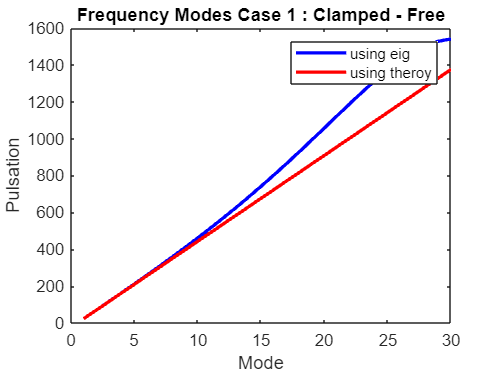


% We notice a difference between theroy and eig from matlab
% We will now plot the diffrence between the two
x = 1:nel;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnTh, 'r', 'LineWidth', 2);

title("Frequency Modes Case 1 : Clamped - Free");
xlabel('Mode');
ylabel('Pulsation');
legend('using eig', 'using theroy');

hold off;

**Conlcusion :**

- We adapted the matrix by removing first degree of freedom

- We made the computations of 10 natural frequancies using eigs(K,M)

- We did the same using therocal formula (10)

- We ploted both to show the delta between the two

- Everything went well, we can move on tot he final case

%CASE 2 : free-free rod

% solve for w, natural frequencies of the bars.
% USING EIG from MATLAB:

[~,wnDiag] = eig(K,M);
wnDiag = wnDiag(2:end,2:end); %we remove first one (-0)
wnEig = sqrt(diag(wnDiag));
disp("Case 2 : Natural frequencies using eig()");

Case 2 : Natural frequencies using eig()


disp(wnEig');

   1.0e+03 *

    0.0466    0.0934    0.1404    0.1878    0.2358    0.2843    0.3337    0.3839    0.4352    0.4877    0.5414    0.5965    0.6531    0.7113    0.7711    0.8324    0.8952    0.9594    1.0246    1.0904    1.1562    1.2212    1.2842    1.3439    1.3988    1.4472    1.4872    1.5172    1.5358    1.5421




% USING THERORY :

%(...)

% We go through k = 1  to 10 to computute 10 first mode
wnTh = zeros(nel,1);
for k = 1:nel % boucle sur les modes de fréquences
    wnTh(k) = (c0/L)*k*pi;
end

disp("Case 2 : Natural frequencies using therory");

Case 2 : Natural frequencies using therory


disp(wnTh');

   1.0e+03 *

    0.0466    0.0932    0.1399    0.1865    0.2331    0.2797    0.3263    0.3729    0.4196    0.4662    0.5128    0.5594    0.6060    0.6527    0.6993    0.7459    0.7925    0.8391    0.8857    0.9324    0.9790    1.0256    1.0722    1.1188    1.1654    1.2121    1.2587    1.3053    1.3519    1.3985



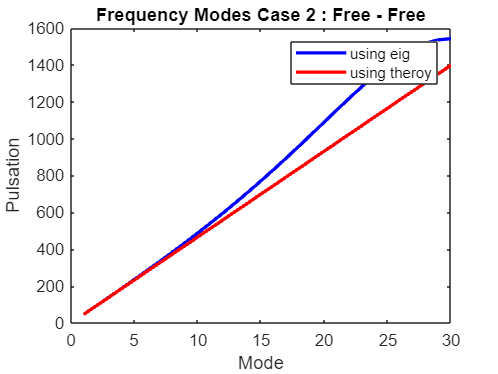


%Once again we have similar resuts but a delta seems to appear
%We plot it


x = 1:nel;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnTh, 'r', 'LineWidth', 2);

title("Frequency Modes Case 2 : Free - Free")
xlabel('Mode');
ylabel('Pulsation');
legend('using eig', 'using theroy');

hold off;

**Conlcusion :**

- We used matrix WITH first degree of freedom

- We made the computations of 10 natural frequancies using eigs(K,M)

- We did the same using therocal formula (10)

- We ploted both to show the delta between the two

- Everything went just like in case 1 except the frequencies are not the same.

% md [3 0; 0 3] VS mc [2 1 ; 1 2]

%We now want to compare those solutions using the diagonal mass matrix Md
%computed at the beginning of this file

% To do so, we redo the second case using Md

[u,wnDiagD] = eig(K,Md);
wnDiagD = wnDiagD(2:end,2:end); %we remove first one (-0)
wnEigD = sqrt(diag(wnDiagD));
disp("Case 2 BIS : Natural frequencies using eig() and Md diagonal mass matrix");

Case 2 BIS : Natural frequencies using eig() and Md diagonal mass matrix


disp(wnEigD');

   46.5967   93.0657  139.2796  185.1117  230.4365  275.1296  319.0687  362.1332  404.2051  445.1691  484.9129  523.3277  560.3080  595.7525  629.5642  661.6502  691.9227  720.2987  746.7004  771.0555  793.2971  813.3644  831.2023  846.7619  860.0007  870.8822  879.3767  885.4608  889.1180  890.3382



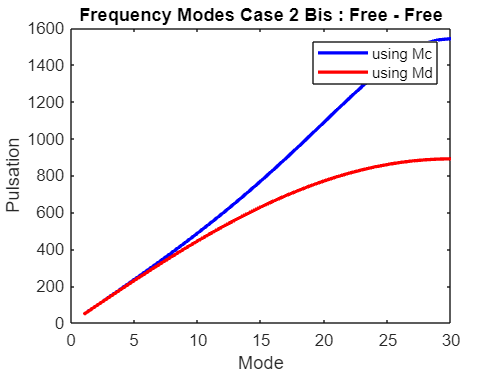


% Now we compare The first results (that we got earlier doing the second case
%) and the brand new results using a diagonal mass matrix.

x = 1:nel;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnEigD, 'r', 'LineWidth', 2);

title("Frequency Modes Case 2 Bis : Free - Free")
xlabel('Mode');
ylabel('Pulsation');
legend('using Mc', 'using Md');

hold off;


%We observe a big delta comming, almost a factor 2 towards the mode k=10 !

**Note : Please execute the code sections in the right order for tyhis to work**

**Conlcusion :**

- We re-computed de second case using Md, the diagonal matrix

- We ploted our old and our new natural frequancies toi compare

- We saw a big difference. Better use Mc in the future !